# Project: GDP regression

## Explanatory analysis

### Descriptive statistics

file = 'data/taiwan.csv'

file = 'data/taiwan.csv'

data = readtable(file);
format compact
summary(data)

Variables:
    YEAR: 51×1 double
        Values:
            Min        1950 
            Median     1975 
            Max        2000 
    CC: 51×1 double
        Values:
            Min            8.2701 
            Median         20.968 
            Max            55.05  
            NumMissing     3      
    CC2: 51×1 double
        Values:
            Min            50.712 
            Median         61.971 
            Max            75.523 
            NumMissing     3      
    KC: 51×1 double
        Values:
            Min            54.209 
            Median         62.33  
            Max            69.397 
            NumMissing     3      
    CSAVE: 51×1 double
        Values:
            Min            2.6085 
            Median         22.927 
            Max            34.119 
            NumMissing     3      
    XRAT: 51×1 double
        Values:
            Min 

t =  data.Properties.VariableNames;
stats = describe(data)

stats = 7×20 table
    YEAR      CC       CC2      KC      CSAVE    XRAT      CG       KG       CI       KI      OPENK     OPENC        POP          PC        PG        P         PI      CGNP       CGDP       statistics
    ____    ______    _____    _____    _____    _____    _____    _____    _____    _____    ______    ______    __________    ______    ______    ______    __

%writetable(stats,'summary_stats_china.csv')

Histogram plots

figure
for col = 2:size(data,2)
    %subplot(6,3,col-1)
    %histogram(data.(col))
    %title(strcat('Distribution :',data.Properties.VariableNames{col}))
end

Correlation analysis

matrix = preprocess(file)

matrix = 	1.0e+04 *

    0.0001    0.1951    0.0008    0.0073    0.0067    0.0004    0.0010    0.0022    0.0030    0.0009    0.0007    0.0015    0.0025    0.8255    0.0079    0.0064    0.0080    0.0130    0.0181
    0.0001    0.1952    0.0009    0.0074    0.0069    0.0004    0.0010    0.0021    0.0029    0.0010    0.0008    0.0017    0.0022    0.8541    0.0096    0.0077    0.0096    0.0144    0.0203
    0.0001    0.1953    0.0009    0.0074    0.0069    0.0006    0.0016    0.0020    0.0028    0.0011    0.0009    0.0017    0.0022    0.8822    0.0078    0.0058    0.0076    0.0098    0.0219
    0.0001    0.1954    0.0010    0.0076    0.0069    0.0003    0.0016    0.0022    0.0029    0.0011    0.0009    0.0015    0.0021    0.9134    0.0076    0.0065    0.0077    0.0113    0.0230
    0.0001    0.1955    0.0010    0.0073    0.0068    0.0004    0.0016    0.0023    0.0029    0.0009    0.0007    0.0013    0.0021    0.9480    0.0082    0.0070    0.0083    0.0130    0.0244
    0.0001    0.1956    

corr = corrcoef(matrix(:,2:end))

corr =     1.0000    0.9651   -0.7121   -0.6545    0.8635    0.1869   -0.9079   -0.9577    0.7787    0.8704    0.9804    0.8858    0.9967    0.3067    0.6504    0.4079   -0.1097    0.8832
    0.9651    1.0000   -0.5357   -0.4888    0.7443   -0.0415   -0.9162   -0.9046    0.6592    0.7739    0.9534    0.7696    0.9423    0.4865    0.7919    0.5659    0.0696    0.9696
   -0.7121   -0.5357    1.0000    0.9582   -0.9483   -0.5744    0.6249    0.7641   -0.6896   -0.7208   -0.7208   -0.8825   -0.7624    0.1818   -0.1094    0.0746    0.4561   -0.3301
   -0.6545   -0.4888    0.9582    1.0000   -0.8884   -0.5232    0.5489    0.6916   -0.6122   -0.6302   -0.6686   -0.8461   -0.7051    0.1529   -0.1106    0.0530    0.3864   -0.2845
    0.8635    0.7443   -0.9483   -0.8884    1.0000    0.3733   -0.8403   -0.9219    0.7684    0.8294    0.8844    0.9538    0.8944    0.0846    0.3845    0.1921   -0.2699    0.5733
    0.1869   -0.0415   -0.5744   -0.5232    0.3733    1.0000    0.0628   -0.1580    0.35

figure
h = heatmap(corr,"Colormap",flipud(colormap('parula')))

h =   HeatmapChart with properties:

        XData: {18×1 cell}
        YData: {18×1 cell}
    ColorData: [18×18 double]

  Show all properties

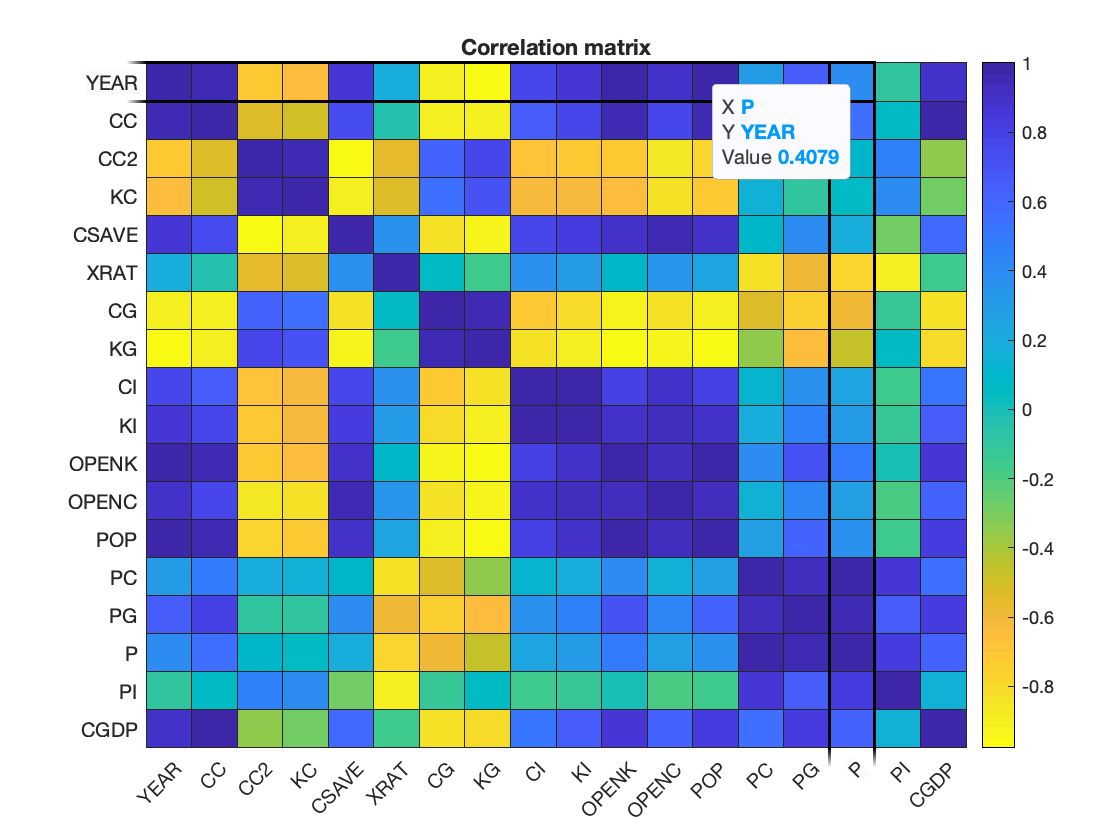

h.Title  = 'Correlation matrix';
feature_names = ["YEAR","CC","CC2","KC","CSAVE","XRAT","CG","KG","CI","KI","OPENK","OPENC","POP","PC","PG","P","PI","CGDP"];
h.XDisplayLabels = feature_names;
h.YDisplayLabels = feature_names;


% data seems colinear => test condition number (without GDP)
X = matrix(:,1:end-1)

X = 	1.0e+04 *

    0.0001    0.1951    0.0008    0.0073    0.0067    0.0004    0.0010    0.0022    0.0030    0.0009    0.0007    0.0015    0.0025    0.8255    0.0079    0.0064    0.0080    0.0130
    0.0001    0.1952    0.0009    0.0074    0.0069    0.0004    0.0010    0.0021    0.0029    0.0010    0.0008    0.0017    0.0022    0.8541    0.0096    0.0077    0.0096    0.0144
    0.0001    0.1953    0.0009    0.0074    0.0069    0.0006    0.0016    0.0020    0.0028    0.0011    0.0009    0.0017    0.0022    0.8822    0.0078    0.0058    0.0076    0.0098
    0.0001    0.1954    0.0010    0.0076    0.0069    0.0003    0.0016    0.0022    0.0029    0.0011    0.0009    0.0015    0.0021    0.9134    0.0076    0.0065    0.0077    0.0113
    0.0001    0.1955    0.0010    0.0073    0.0068    0.0004    0.0016    0.0023    0.0029    0.0009    0.0007    0.0013    0.0021    0.9480    0.0082    0.0070    0.0083    0.0130
    0.0001    0.1956    0.0010    0.0072    0.0065    0.0003    0.0025    0.002

%[condition_nb,~,~] = colinearity_analysis(X)

### scatter plot for between each feature and GDP

%figure
for col = 1:size(data,2)-1
    %subplot(6,3,col)
    %scatter(data.(col),data.CGDP)
    %xlabel(data.Properties.VariableNames{col})
    %ylabel('CGDP')
end